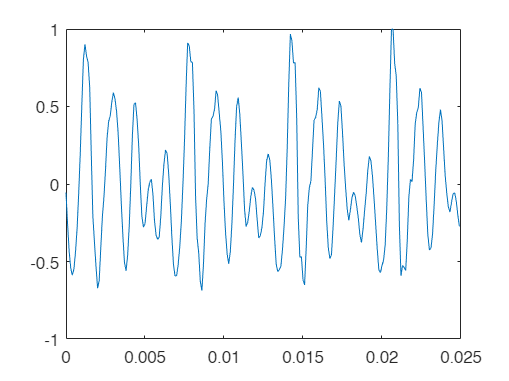

load('./ex2M1.mat');
fs = 10000;
range = 0:(1/fs):(0.025-1/fs);
plot(range, speech1_10k);

speech1_10k;

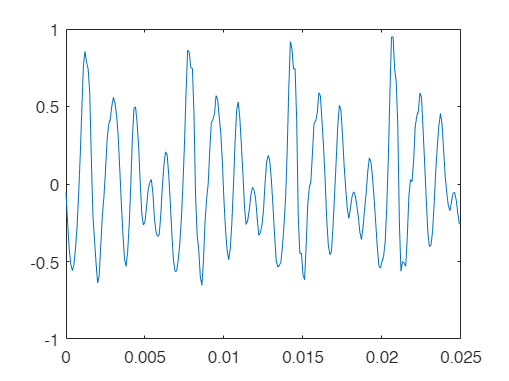

[y, Fs] = audioread('./speech1_10k.wav');
plot(range, y);

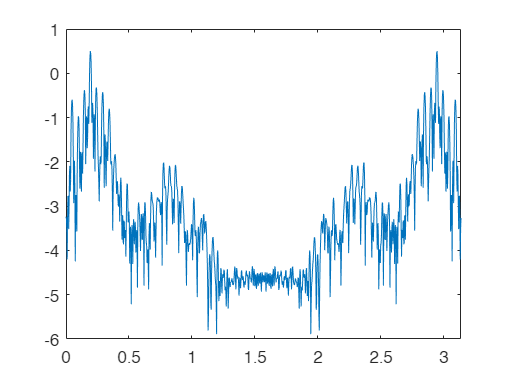

n = 1024;
Y = fft(speech1_10k, n);
range_Y = 0:(pi/n):pi*(1-1/n);
power = abs(Y).^2/n;
plot(range_Y, log10(power));

% loglog(range_Y, power);

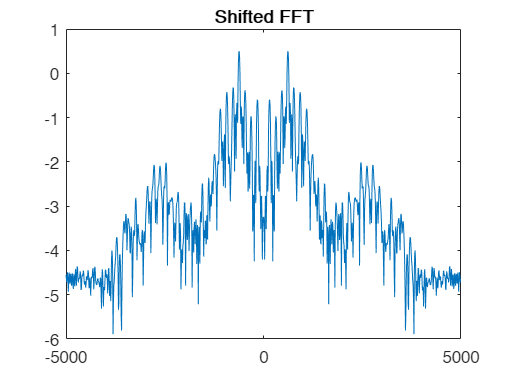

fft_shifted_val = fftshift(Y);
range_fft_shifted_val = (-n/2 : n/2 - 1) * (fs/n);
powershift = abs(fft_shifted_val).^2/n;
plot(range_fft_shifted_val, log10(powershift))
title("Shifted FFT")

% Ignore the warning of Negative data ignored, its due to the shifting of
% fft, so its symmetric about 0.

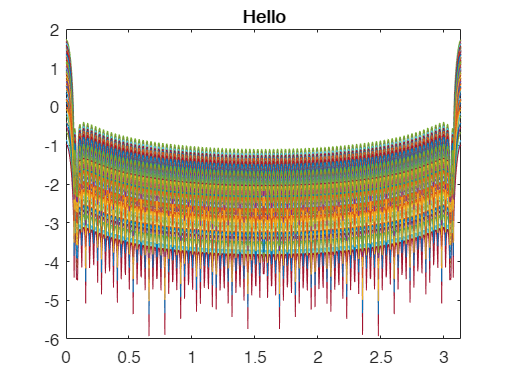

% wvtool(hamming(10));
ham_10 = zeros(250, 1);
ham_10(125-50:125+49) = hamming(100, "symmetric");
windowed_10 = (speech1_10k .* ham_10);
windowed_fft_10 = abs(fft(windowed_10, n));
plot(range_Y, log10(windowed_fft_10));
title("Hello")

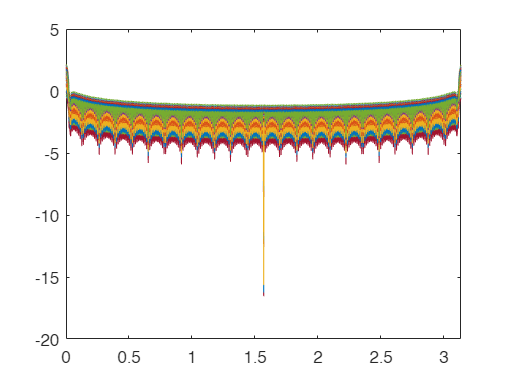

ham_25 = hamming(250, "periodic");
windowed_25 = abs(fft(speech1_10k .* ham_25, n));

plot(range_Y, log10(windowed_25))

% ham_125 = zeros(250, 1);
% ham_125(125-62:125+62) = hamming(125, "symmetric");
% windowed_125 = speech1_10k .* ham_125;
% loglog(range, windowed_125)